# **Analysis of seroprevalence data using LSM**

## **Part I: Fitting the catalytic model to seroprevalence data to estimate the force of infection**

#### UK

We will first analyze the data from the UK (“seroprevalence_uk”):

Ignoring the maternal antibodies, write the formula for the proportion of age "a" who have ever been infected in terms of force of infection "$\lambda$".

addpath("./lib");
addpath("./data");

uk.raw = upload_data_part1("./data/seroprevalence_uk.csv");
uk.age = uk.raw(:,1);
uk.seroprevalence = uk.raw(:,2);

1 Assume the initial value for the force infection in the UK to be 0.1. Do you think the true value for the force infection in the UK was greater or smaller than that currently assumed? What is the current value for the $L^2$-error?

initial_guess = 0.10; 
sp_uk_guess = get_seroprev_from_foi(uk.age, initial_guess);
cost_uk_guess = get_l2_error(uk.seroprevalence, sp_uk_guess);
fprintf("The L2 error before estimation is %.4f", cost_uk_guess);

The L2 error before estimation is 0.4355

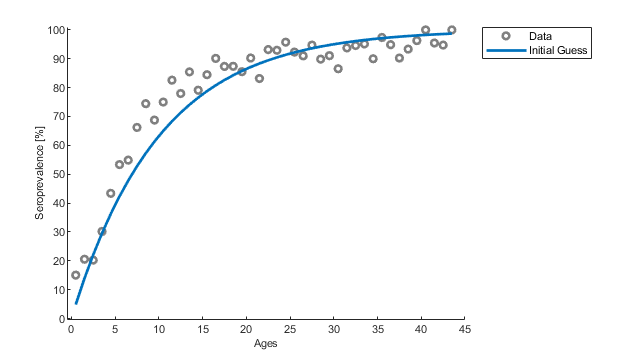

draw_seroprev_guess(uk.age, uk.seroprevalence, sp_uk_guess)

- We can see the true FoI is greater than now.

2 What is the best-fitting value for the force of infection and the current value for the $L^2$-error? Plot a graph of model predictions and observed data.

[estimated_foi, cost_uk_best] = estimate_foi(uk.age, uk.seroprevalence, initial_guess);
fprintf("The estimated FoI value is %.4f", estimated_foi);

The estimated FoI value is 0.1223

fprintf("The L2 error after estimation is %.4f", cost_uk_best);

The L2 error after estimation is 0.3295

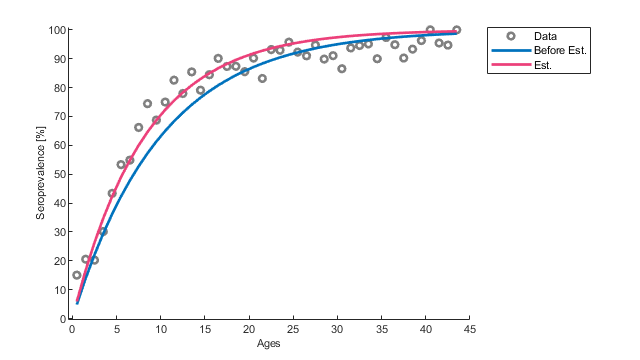

sp_uk_est = get_seroprev_from_foi(uk.age, estimated_foi);
uk_result = draw_seroprev_estimate(uk.age, uk.seroprevalence, sp_uk_guess, sp_uk_est);

3 For which age groups does the model underestimate the proportion of individuals who are seropositive? For which age groups does it overestimate it?

- The sero-prevalences of the young who are less than about 15 are underestimated. At the same time, the ones from the others are overestimated.

4 According to the formula, what is the average age at infection in the UK assuming that the force of infection is independent of age?

- Assuming rectangular population structure by age, average age at infection, $A$, can be written as $A=\frac{1}{\lambda}$ . In our case, $A$ is 

A = 1/estimated_foi

A = 8.1771

.

5 Assuming that the average life expectancy ($L$) is 60 years, what is the $R_0$ for this population according to the expression $R_0=\frac{L}{A}$? What is the herd immunity threshold?

- $R_0$ is 

L = 60;
R0 = L/A

R0 = 7.3375

-  HIT, which can be get as $1-\frac{1}{R_0}$ from it is 

HIT = 100*(1-1/R0)

HIT = 86.3715

 which means the minimal proportion of the protected (by anything) for curbing transmission of disease.

#### China

Fit the catalytic model to China data (“seroprevalence_china”) to estimate the force of infection:

ch.raw = upload_data_part1("./data/seroprevalence_china.csv");
ch.age = ch.raw(:,1);
ch.seroprevalence = ch.raw(:,2);

6 Determine the best-fitting force of infection and plot a graph of model predictions and observed data. Calculate the average age at infection, the $R_0$ (assuming that the life expectancy is the same as that in the UK) and herd immunity.

initial_guess = 0.10; 
sp_ch_guess = get_seroprev_from_foi(ch.age, initial_guess);
cost_ch_guess = get_l2_error(ch.seroprevalence, sp_ch_guess);
fprintf("The L2 error before estimation is %.4f", cost_ch_guess)

The L2 error before estimation is 0.7969

[estimated_foi, cost_ch_best] = estimate_foi(ch.age, ch.seroprevalence, initial_guess);
fprintf("The estimated FoI value is %f", estimated_foi);

The estimated FoI value is 0.278864

fprintf("The L2 error after estimation is %.4f", cost_ch_best);

The L2 error after estimation is 0.2345

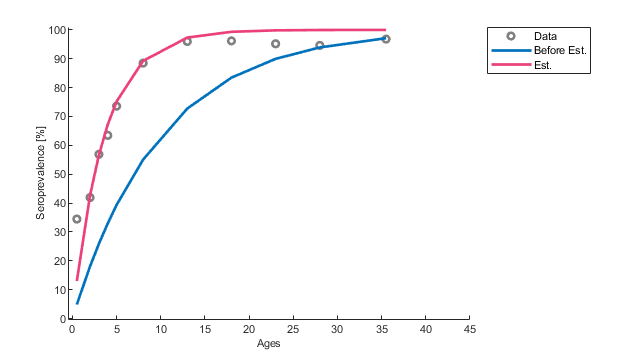

sp_ch_est = get_seroprev_from_foi(ch.age, estimated_foi);
ch_result = draw_seroprev_estimate(ch.age, ch.seroprevalence, sp_ch_guess, sp_ch_est);

- Average age at infection, $A$ 

A = 1/estimated_foi

A = 3.5860

- The basic reproduction number, $R_{0\;}$, with assumption of $L=60$

L = 60;
R0 = L/A

R0 = 16.7318

- The HIT is

HIT = 100*(1-1/R0)

HIT = 94.0234

7 How do the values for the force of infection, average age at infection, $R_0$ and herd immunity threshold in China compare against those for the UK? Suggest possible reasons for these differences.

- The risk of infection of China is larger, which causes early infection, high $R_0$ and HIT. The main difference is the positive ratio of the young. This is for hygiene problems or if the seroprevalence data of China is collected after vaccination program begins, it can increase the number of sero-positive ratio of the young.

8 Modify the expression for the prevalence of previous infection at each age assuming that individuals are immune for the first 6 months of life as a result of maternal antibodies.

- The original catalytic analysis says proportions of seropositive people aged $a$ is $1-e^{-\lambda \;a}$. When we applied the maternal immunity into it, which gives perfect protections to the less-than-6-months-aged children, we should regard the seroprevalence ratio of the aged-$a$ of data as the one of the aged-($a-0\ldotp 5$). Therefore, the fitting function has the form of $1-e^{-\lambda \left(a-0\ldotp 5\right)}$.

#### Maternality

9 Assuming that individuals are immune for the first 6 months of life and are then susceptible, refit the model to estimate the force of infection in the UK and China. Plot a graph of model predictions and observed data.

[estimated_foi, ~] = estimate_foi_with_maternality(uk.age, uk.seroprevalence, initial_guess);
fprintf("Estimated FoI of UK with considering maternality is %.4f\n", estimated_foi)

Estimated FoI of UK with considering maternality is 0.1305


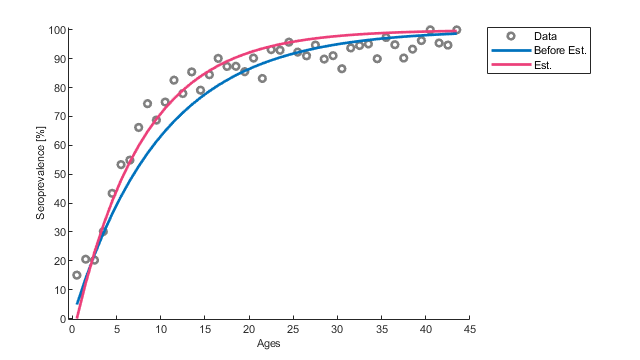

sp_uk_est_with_maternality = get_seroprev_from_foi_with_maternality(uk.age, estimated_foi);
uk_result_with_maternality = draw_seroprev_estimate(uk.age, uk.seroprevalence, sp_uk_guess, sp_uk_est_with_maternality);

[estimated_foi, ~] = estimate_foi_with_maternality(ch.age, ch.seroprevalence, initial_guess);
fprintf("Estimated FoI of China with considering maternality is %.4f\n", estimated_foi)

Estimated FoI of China with considering maternality is 0.3113


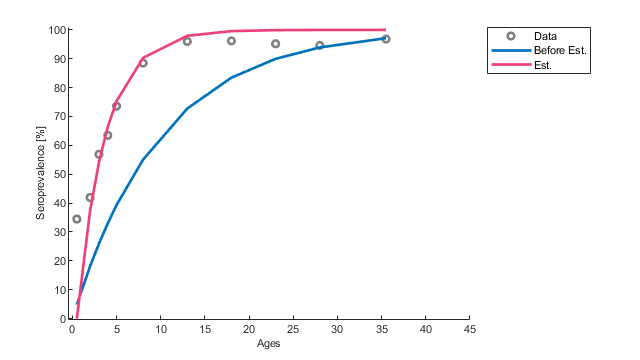

sp_ch_est_with_maternality = get_seroprev_from_foi_with_maternality(ch.age, estimated_foi);
ch_result_with_maternality = draw_seroprev_estimate(ch.age, ch.seroprevalence, sp_ch_guess, sp_ch_est_with_maternality);

#### Age-specific FoI

Plot the graphs of $-\ln \left(\frac{S_a }{N_{a\;} }\right)$ for the UK and China, where $S_a$ is the number of susceptible at age “$a$” and $N_a$ is the number of population at age “$a$”.

uk.neg_log_SN = -log(1-uk.seroprevalence);
ch.neg_log_SN = -log(1-ch.seroprevalence);

- Draw a plot for UK

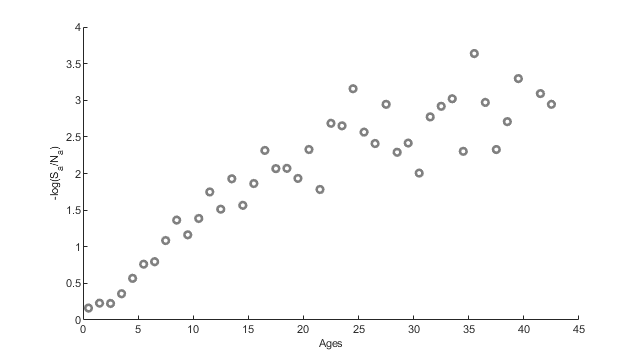

figure("Units","pixels","Position",[10,10,640,360]);
hold on;

plot(uk.age, uk.neg_log_SN, ...
    "o", "MarkerSize", 5, "LineWidth", 2, "Color", [0.5, 0.5, 0.5]);

xlabel("Ages");
ylabel("-log(S_a/N_a)");
set(findall(gcf,"-property","FontSize"),"FontSize",8);

- Draw a plot for China

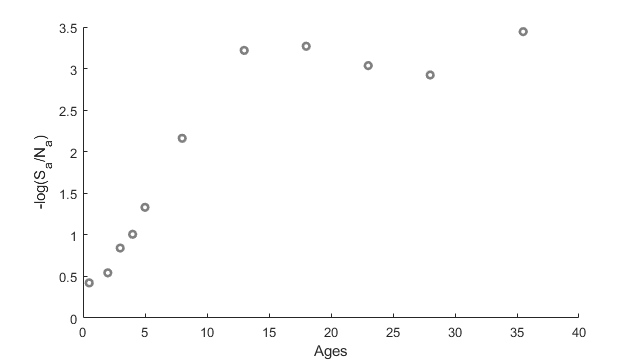

figure("Units","pixels","Position",[10,10,640,360]);
hold on;

plot(ch.age, ch.neg_log_SN, ...
    "o", "MarkerSize", 5, "LineWidth", 2, "Color", [0.5, 0.5, 0.5]);

xlabel("Ages");
ylabel("-log(S_a/N_a)");

10 According to the plots, is the assumption that the force of infection is independent of age in these populations justified? At what age does it look as though the force of infection changes in these populations?

- A single age-independent FOI can’t be justified with two graphs. People have different values of FOI before-and-after around 15 years old.

11 Estimate the age-specific forces of infection using 2 age groups for the UK and China. Suggest reasons for the differences in the force of infection between China and the UK.

- Set the age-specific force of infection and make a function to produce seroprevalence from the catalytic model with age-specific FoI, named `get_seroprev_from_foi_with_age_specificity`.

With the example of 2 age groups differentiated at 15-years-old, the analytic solution of catalytic model is


$$s(a)=\begin{cases}
e^{-\lambda_1a} & \text{ for } a<15\\
e^{-15(\lambda_1-\lambda_2)}e^{-\lambda_2a} & \text{ for } a\ge15
\end{cases}$$


Therefore, the sero-prevalence for each age is


$$z(a)=\begin{cases}
1-e^{-\lambda_1a} & \text{ for } a<15\\
1-e^{-15(\lambda_1-\lambda_2)}e^{-\lambda_2a} & \text{ for } a\ge15
\end{cases}$$


initial_guess = [0.1 0.1]

initial_guess =     0.1000    0.1000


[estimated_foi, ~] = estimate_foi_with_age_specificity(uk.age, uk.seroprevalence, initial_guess);
fprintf("Estimated age-specific FoI of UK is %.4f (less than 15) and %.4f (greater than or equal to 15)\n", estimated_foi(1), estimated_foi(2));

Estimated age-specific FoI of UK is 0.1306 (less than 15) and 0.0448 (greater than or equal to 15)


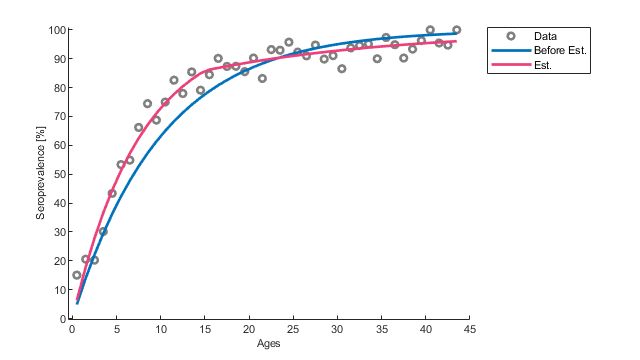

sp_uk_est_with_age_specificity = get_seroprev_from_foi_with_age_specificity(uk.age, estimated_foi);
uk_result_with_age_specificity = draw_seroprev_estimate(uk.age, uk.seroprevalence, sp_uk_guess, sp_uk_est_with_age_specificity);

[estimated_foi, ~] = estimate_foi_with_age_specificity(ch.age, ch.seroprevalence, initial_guess);
fprintf("Estimated age-specific FoI of China is %.4f (less than 15) and %.4f (greater than or equal to 15)\n", estimated_foi(1), estimated_foi(2));

Estimated age-specific FoI of China is 0.2761 (less than 15) and 0.0000 (greater than or equal to 15)


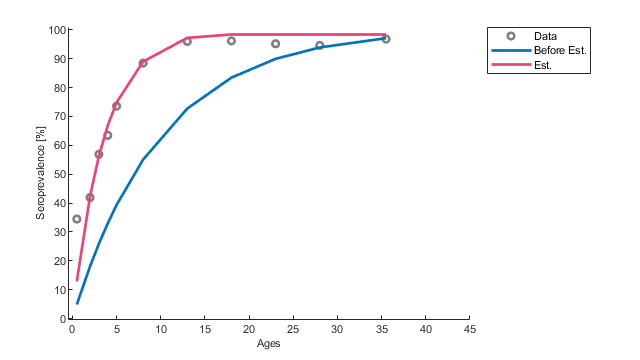

sp_ch_est_with_age_specificity = get_seroprev_from_foi_with_age_specificity(ch.age, estimated_foi);
ch_result_with_age_specificity = draw_seroprev_estimate(ch.age, ch.seroprevalence, sp_ch_guess, sp_ch_est_with_age_specificity);

The seropositivity of the young is different. Reasons for this difference make the other differences. The difference of household hygiene or contacts of the young, which is a possible route of transmission, be the reason.

## Part II: **Fitting transmission model to prevalence data to estimate the transmission rate**

Set up the SEIR model of the transmission dynamics of measles in a closed population using differential equations.

We assume that individuals mix randomly and parameter and initial values are given as follows: 

- Population: 100000 people

- Pre-infectious period: 8 days

- Infectious period: 7 days

- Initial values: (S,E,I,R)=(99999,0,1,0)

Fit the model to prevalence data to estimate the transmission rate (“incidence_measles”):

raw_data = upload_data_part2("./data/incidence_measles.csv");

DAYS_PER_WEEK = 7;
time_week = raw_data(:,1)/DAYS_PER_WEEK;
time_end_day = raw_data(end,1);
weekly_incidence = raw_data(:,2);

params = set_params();
initial_guess = 1e-5;

12 What is the best-fitting value for the transmission rate? Plot a graph of model predictions and observed data.

- Find the best-fitting transmission rate $\beta \;$ with the above parameter sets and initial guess.

estimated_beta = estimate_beta(raw_data, params, initial_guess);
fprintf("The estimated value of beta is %.4g", estimated_beta);

The estimated value of beta is 1.858e-05

- Draw a plot of solution with the parameters including `estimated_beta` value and `initial_guess`. Plot should include the data points also.

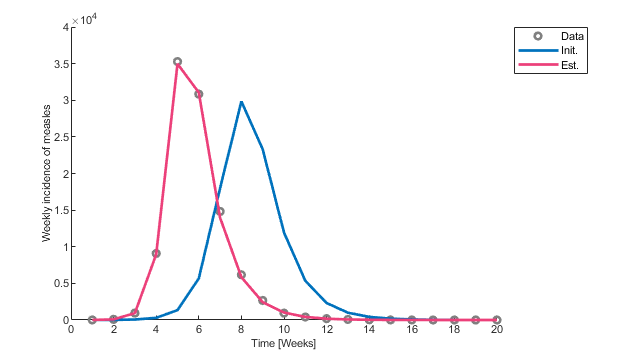

figure("Units", "pixels", "Position",[10,10,640,360]);
hold on;

plot(time_week, weekly_incidence, ...
    "o", "MarkerSize", 5, "LineWidth", 2, "Color", [0.5, 0.5, 0.5]);

initial_guess_sol = solve_SEIR(initial_guess, params, time_end_day);
initial_guess_weekly_incidence = get_weekly_incidence_from_sol(initial_guess_sol, params.f);
plot(time_week, initial_guess_weekly_incidence, ...
    "LineWidth", 2, "Color", [0, 0.4470, 0.7410]);

estimated_sol = solve_SEIR(estimated_beta, params, time_end_day);
estimated_weekly_incidence = get_weekly_incidence_from_sol(estimated_sol, params.f);
plot(time_week, estimated_weekly_incidence, ...
    "LineWidth", 2, "Color", [0.9255, 0.2510, 0.4784]);

xlabel("Time [Weeks]");
ylabel("Weekly incidence of measles");
legend(["Data", "Init.", "Est."], "Location", "northeastoutside");
set(findall(gcf,"-property","FontSize"),"FontSize",8);

13 Calculate $R_{0\;}$ and herd immunity threshold.

- $R_{0\;}$ is $\frac{\beta N}{\gamma \;}$ which is

R0 = estimated_beta*params.N/params.r

R0 = 13.0084

- 
$$\mathrm{HIT}=1-\frac{1}{R_0 }$$


HIT = 1-1/R0

HIT = 0.9231